## Data Preprocessing and Custom Training Function

### Εισαγωγή δεδομένων και μια προεπεξεργασία

Σε αυτό το Notebook θα δούμε πως επεξεργαζόμαστε τα δεδομένα και πως μπορούμε να δημιουργήσουμε την δική μας επαναληπτική διαδικασία/training loop αντί να χρησιμοποιούμε την έτοιμη συνάρτηση **train Network **με στόχο την μεγαλύτερη ευελιξία.

Αρχικά,θα δούμε λίγο πως να επεξεργαζόμαστε τα δεδομένα μας, εφαρμόζοντας **φίλτρα**,**στατιστικούς** **ελέγχους** αλλά και διάφορους **μετασχηματισμούς/feature engineering.**

Χρησιμοποιούμε την συνάρτηση get_hippo()_data όπως και στο τελευταίο Notebook ώστε να εισαγάγουμε τα δεδομένα μας στο workspace.

clear all
close all
data = get_hippo_data()

data = 451228×11 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    RotSpeed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    ________    ____________    __________    _____________________

       0    167.5          2.6          7.1378            239                 4                 10            800.46         4.034           0                152.31        
    0.01    167.5          2.6          7.1378            239                 4    

data = sortrows(data, "Time");
head(data)

    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    RotSpeed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    ________    ____________    __________    _____________________

       0    167.5          2.6          7.1378            239                 4                 10            800.46         4.034           0                152.31        
    0.01    167.5          2.6          7.1378            239                 4                 10        

Για να έχουμε μία γρήγορη περιγραφή των δεδομένων μας μπορούμε να χρησιμοποιήσουμε τη έτοιμη συνάρτηση summary που κάνει ακριβώς αυτό που σημαίνει, περιγράφει συνοπτικά τα δεδομένα μας, αν είναι αριθμητικά τότε μας δίνει min, median και max και αν είναι κατηγορικά τότε μας δίνει την συχνότητα κάθε παρατήρησης.

summary(data)

Variables:

    Time: 451228×1 double

        Values:

            Min             0 
            Median     2256.1 
            Max        4512.3 

    NOx: 451228×1 double

        Values:

            Min          18.4 
            Median      348.7 
            Max        1226.9 

    FuelConsumption: 451228×1 double

        Values:

            Min         0.35  
            Median     23.35  
            Max         65.4  

    lambda: 451228×1 double

        Values:

            Min        1.1461 
            Median     1.6687 
            Max        134.63 

    ExhaustGasMassFlow: 451228×1 double

        Values:

            Min         237.4 
            Median      558.6 
            Max        1318.4 

    IntakePressure: 451228×1 double

        Values:

            Min           2   
            Median       54   
            Max         198   

    TorqueRefe

stats = grpstats(data,'lambda', {'mean'})

stats = 7398×12 table
               lambda    GroupCount    mean_Time    mean_NOx    mean_FuelConsumption    mean_ExhaustGasMassFlow    mean_IntakePressure    mean_TorqueReference    mean_RotSpeed    mean_EngineTorque    mean_EGRCommand    mean_ExhaustGasTemperature
               ______    __________    _________    ________    ____________________    _______________________    ___________________    ____________________    _____________    _________________    _______________    __________________________

    1.14605    1.1461        10         1708.6        437.5 

Χρησιμοποιούμε τις εντολές head και tail για να δούμε γρήγορα τις πρώτες k γραμμές καθώς και τις τελευταίες k γραμμές του table.

k=5;
head(data,k)

    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    RotSpeed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    ________    ____________    __________    _____________________

       0    167.5          2.6          7.1378           239                  4                 10            800.46         4.034           0                152.31        
    0.01    167.5          2.6          7.1378           239                  4                 10        

tail(data,k)

     Time      NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    RotSpeed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ______    _____    _______________    ______    __________________    ______________    _______________    ________    ____________    __________    _____________________

    4512.2    127.1         12.2          4.3371          686.2                 44                19            1897.4        36.911         18.98              251.19        
    4512.2    127.1         12.2          4.3371          686.2                 44                19

Στη συνέχεια ελέγχουμε για Nan values δηλαδή για εγγραφές που είναι κενές ή έχουν την τιμή Nan χρησιμοποιώντας τη συνάρτηση **isnan** που μας γυρνά ένα ένα λογικό πίνακα με τιμές **1** όπου έχουμε τιμή **Nan** και τιμές **0** όπου έχουμε κανονικές τιμές. Παρατηρούμε πως αν χρησιμοποιήσουμε την συνάρτηση **sum** κατά στήλη τότε μπορούμε να δούμε τον συνολικό αριθμό Nan values ανά στήλη. Προφανώς έχουμε μερικές **Nan** τιμές στην **5η** στήλη που είναι η μεταβλητή **total_bedrooms**. 

indexes = isnan(data{:,:});
sum(isnan(data{:,:}))

ans =      0     0     0     0     0     0     0     0     0     0     0


Ένας άλλος τρόπος να ελέγχεξουμε αν δεν υπάρχουν εγγραφές είναι να χρησιμοποιήσουμε την εντολή **ismissing**

sum(ismissing(data{:,:}))

ans =      0     0     0     0     0     0     0     0     0     0     0


Ελέγχουμε αν όντως είναι Nan.

data(indexes(:,5),:)


ans =

  0×11 empty table



Υπάρχουν διάφοροι τρόποι να αντιμετωπίσει κανείς τις Nan τιμές και γενικά τις μη ομαλές τιμές όπως Null, ' ' αλλά και πιθανά outliers όπως θα δούμε παρακάτω. Η πιο απλή λύση είναι απλώς να παραλείψουμε αυτά τα ελαττωματικά δεδομένα χρησιμοποιώντας την εντολή `rmmissing.`

%data = rmmissing(data);

Αντί για παράλειψη θα μπορούμε να αντικαταστήσουμε τις τιμές με είτε τη μέση τιμή ενός παραθύρου γύρω από την τιμή(moving average) είτε με την μέση τιμή όλου του δείγαμτός.

[R] = corr(data{:,2:end});

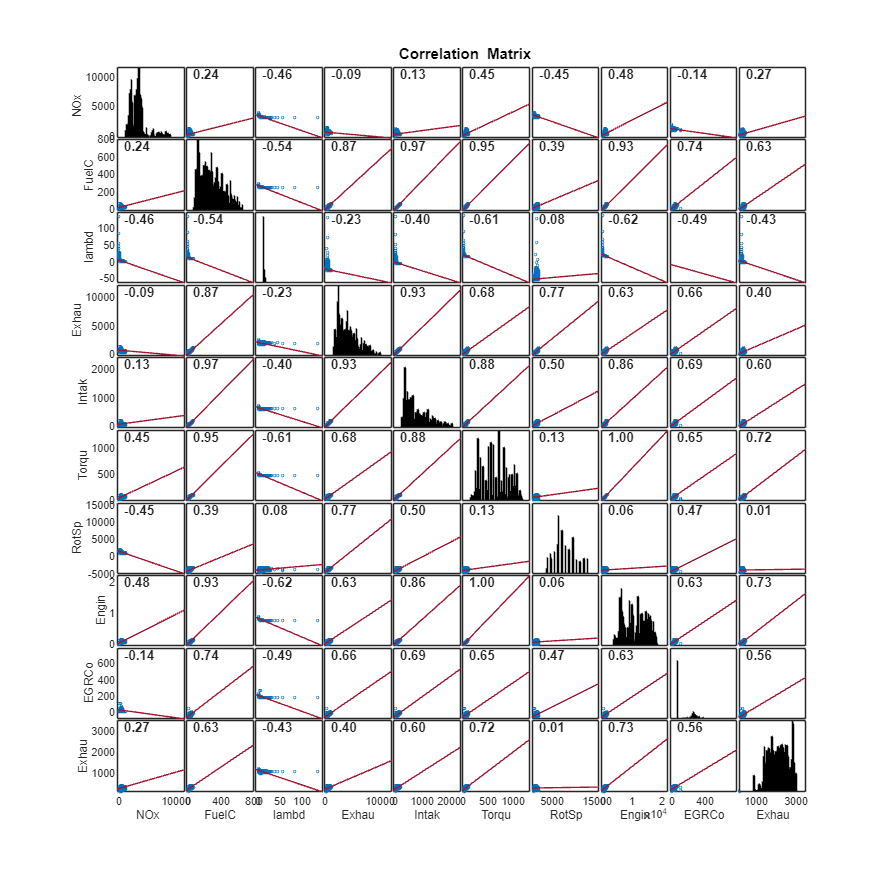

% Visualize the data 
f = figure;
f.Position(3:4) = [6000, 6000];

corrplot(data(:,["NOx", "FuelConsumption", "lambda", "ExhaustGasMassFlow", "IntakePressure", "TorqueReference", "RotSpeed", "EngineTorque", "EGRCommand", "ExhaustGasTemperature"]))

Αν θέλουμε να δούμε απλώς τους συντελεστές μπορούμε να χρησιμοποιήσουμε την εντολή corrcoef και να αλλάξουμε το αποτέλεσμα σε table ώστε να προσθέσουμε τα ονόματα των στηλών για ευκολότερη ερμηνεία.

% Metaferoume thn sthlh median_house_value sthn arxh gia kaluterh
% optikopoihsh

corr_coeffs = array2table(corrcoef(data{:,["NOx", "FuelConsumption", "lambda", "ExhaustGasMassFlow", "IntakePressure", "TorqueReference", "RotSpeed", "EngineTorque", "EGRCommand", "ExhaustGasTemperature"]}));
corr_coeffs.Properties.VariableNames = ["NOx", "FuelConsumption", "lambda", "ExhaustGasMassFlow", "IntakePressure", "TorqueReference", "RotSpeed", "EngineTorque", "EGRCommand", "ExhaustGasTemperature"];
corr_coeffs{:,:} = round(abs(corr_coeffs{:,:}),2);
corr_coeffs

corr_coeffs = 10×10 table
    NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    RotSpeed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _______________    ______    __________________    ______________    _______________    ________    ____________    __________    _____________________

       1         0.24           0.46            0.09                0.13              0.45            0.45          0.48           0.14               0.27         
    0.24            1           0.54            0.87                0.97              0.95            0.39          0.93           0.74      

### Δημιουργία νέων μεταβλητών

Παρατηρούμε πως η μεταβλητή lambda έχει συσχέτιση μόνο με την μεταβλητή EngineTorque. Για την καλύτερη εκπαίδευση του δικτύου μας θα θέλαμε να δημιουργήσουμε και άλλες μεταβλητές που να έχουν μεγάλη συσχέτιση με την lambda, που από δω και στο εξής θα αναφερόμαστε ως y ή target. 

new_feature_1 = (1./data{:,'NOx'} .* data{:,'ExhaustGasMassFlow'} );
data.new_feature_1 = new_feature_1;
new_feature_2 = 1 ./ data{:,'FuelConsumption'} ;
data.new_feature_2 = new_feature_2;

Παρατηρούμε πως οι 2 νέες μεταβλητές έχουν μεγαλύτερη συσχέτιση, με το lambda, από όλες τις προηγούμενες

corr_coeffs = array2table(corrcoef(data{:,[ "NOx", "FuelConsumption", "lambda", "ExhaustGasMassFlow", "IntakePressure", "RotSpeed", "EngineTorque", "EGRCommand", "ExhaustGasTemperature",...
    "new_feature_1", "new_feature_2"]}));
corr_coeffs.Properties.VariableNames = ["NOx", "FuelConsumption", "lambda", "ExhaustGasMassFlow", "IntakePressure", "RotSpeed", "EngineTorque", "EGRCommand", "ExhaustGasTemperature",...
    "new_feature_1", "new_feature_2"];
corr_coeffs{:,:} = round(abs(corr_coeffs{:,:}),2);
corr_coeffs

corr_coeffs = 11×11 table
    NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    RotSpeed    EngineTorque    EGRCommand    ExhaustGasTemperature    new_feature_1    new_feature_2
    ____    _______________    ______    __________________    ______________    ________    ____________    __________    _____________________    _____________    _____________

       1         0.24           0.46            0.09                0.13           0.45          0.48           0.14               0.27                 0.54             0.33     
    0.24            1           0.54            0.87          

Μπορούμε να δημιουργήσουμε και άλλες νέες μεταβλητές, με γραμμικούς και όχι συνδιασμούς άλλων παραμέτρων ή και με τον εαυτό τους.

Πριν ποχωρήσουμε στην δημιουργία του νευρωνικού μας πρέπει να κάνουμε ένα τελευταίο βήμα και αυτό είναι η κανονικοποίηση των δεδομένων μας, καθώς βρίσκονται σε διαφορετικές κλίμακες και αυτό μπορεί να δημιουργήσει προβλήματα κατά τη διαδικασία της εκπαίδευσης, όπως οι παράγωγοι να πάρουν μεγάλες τιμές(exploding grediensts), αλλά και να γίνει δύσκολη η διαδικασία μάθησης καθώς στο τελευταίο στρώμα τα αποτελέσματα θα πρέπει να έχουν μεγάλα βάρη ώστε από το {-1,1} λόγω της tanh να φτάσουν κοντα στις εκατοντάδες χιλιάδες. Επίσης, για να περάσουμε τα δεδομένα μας ως mini batches στο minibatchqueue object πρέπει να τα μεταφέρουμε σε δομή datastore ώστε το minibatchqueue να τα φέρει σε μορφή dlarray.

% input_columns = (2:13);%[9, 11,13]; % orizoume poies sthles tha xrhsimopoih8oun ws inputs
input_columns = ["new_feature_1", "new_feature_2"];
indexes = randperm(size(data,1)); 
% Xrhsimopoioume to 90% gia training
i_train = floor(size(data,1)/10*9);
i_val = floor(i_train/10) * 9;
num_val_samples = i_train-i_val;
train_data = data(indexes(1:i_train),:);
test_data = data(indexes(i_train:end),:);

 % enwnnoume ta dedomena se morfh (input,targets)
[normalized_data,C,S] = normalize(train_data, "range");
% normalized_data = (data-C)/S 
normalized_data{1,2} *S{1,2}+ C{1,2} == data{indexes(1),2}

ans = logical
   1


normalized_data

normalized_data = 406105×15 table
     Time        NOx       FuelConsumption      lambda      ExhaustGasMassFlow    IntakePressure    TorqueReference    RotSpeed    EngineTorque    EGRCommand    ExhaustGasTemperature    new_feature    new_feature_2    new_feature_3    new_feature_1
    _______    ________    _______________    __________    __________________    ______________    _______________    ________    ____________    __________    _____________________    ___________    _____________    _____________</

S

S = 1×15 table
     Time      NOx      FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    RotSpeed    EngineTorque    EGRCommand    ExhaustGasTemperature    new_feature    new_feature_2    new_feature_3    new_feature_1
    ______    ______    _______________    ______    __________________    ______________    _______________    ________    ____________    __________    _____________________    ___________    _____________    _____________    _____________<

C{:,'lambda'}

ans = 1.1461

data{indexes(1),2}

ans = 327.7000

x_train_ds = arrayDatastore(normalized_data{1:i_val,input_columns}); 
y_train_ds = arrayDatastore(normalized_data{1:i_val,'lambda'});
train_ds = combine(x_train_ds,y_train_ds);

x_val_ds = arrayDatastore(normalized_data{i_val:end,input_columns}); 
y_val_ds = arrayDatastore(normalized_data{i_val:end,'lambda'});
val_ds = combine(x_val_ds,y_val_ds);


### Δημιουργία Δικτύου

Όπώς και στο προηγούμενο μάθημα δημιουργούμε ένα δικό μας νευρωνικό δίκτυο ορίζοντας τα στρώματα(layers)

n_features = size(input_columns,2); % Dialegoume tis tesseris metablhtes me ta kalutera correlations
hippo_layers = [
    featureInputLayer(n_features, 'Name','Input_Layer')
    fullyConnectedLayer(512,'Name','Hidden_Layer_1')
    reluLayer('Name','relu_1')
    fullyConnectedLayer(256,'Name','Hidden_Layer_2')
    reluLayer('Name','relu_2')
    fullyConnectedLayer(128,'Name','Hidden_Layer_3')
    reluLayer('Name','relu_3')
    fullyConnectedLayer(1,'Name','Output_Layer')];

    % regressionLayer Paraleipoume to regressionLayer kathws tha
    % dhmiourghsoume to diko mas training loop

net = dlnetwork(hippo_layers);

### Δημιουργία custom training loop

Περνάμε τα δεδομένα στο minibatchqueue αντικείμενο και του ορίζουμε το μέγεθος του minibatch

numEpochs = 100;
miniBatchSize = 10000;
learnRate = 0.05;
decay = 0.0005;
momentum = 0.9;
numObservationsTrain = train_ds.numpartitions;
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;
averageGrad = [];
averageSqGrad = [];
epoch = 0;
iteration = 0;
validation_freq = 100;
validation_patience = 10;
validation_results = zeros(ceil(numIterations/validation_freq),1);
mbq = minibatchqueue(train_ds,...
    'OutputCast', {'double'  'double'},...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFormat',"BC");
val_mbq = minibatchqueue(val_ds,...
    'OutputCast', {'double'  'double'},...
    'MiniBatchSize',num_val_samples,...
    'MiniBatchFormat',"BC");

Με την εντολή next(mbq) ζητάμε από το αντικείμενο mbq να μας δώσει το επόμενο στη σειρά minibatch και ελέγχουμε πως όλα λειτουργούν σωστά.

Για να ξαναγεμίσουμε τη σειρά απλώς καλούμε την συνάρτηση reset(mqb)

% [x, t] = next(mbq); % Blepoume pws to apotelesma einai 128x4 pinakas gia to X(input data) kai 128x1 gia to t(Target_data)
% % se morfh gpuArray(an exoume CUDA enabled gpu) eidallws aplws dlarray
% forward(net,x);
% reset(mbq)

% An exete egkatesthmeno Matlab 2022b tote mporeite na kalesete to parakatw
% keli kathws kai na kanete uncomment tis grammes sto training loop
monitor = trainingProgressMonitor(Metrics=["TrainingLoss","ValidationLoss"], Info=["Epoch", "LearningRate", "Iteration","RMSE","RMSE_Val"], XLabel="Epoch"); %,"TrainingRMSE", "ValidationRMSE"
%groupSubPlot(monitor,"MSELoss",["TrainingLoss","ValidationLoss"]);
% groupSubPlot(monitor,"MSELoss",["TrainingRMSE", "ValidationRMSE"]);

% Loop over epochs.
while epoch < numEpochs && ~monitor.Stop
    
    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbq);
    
    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop


        iteration = iteration + 1;

        % Read mini-batch of data.
        [x_train,y_train] = next(mbq);

        
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelLoss function and update the network state.
        
        [loss,gradients,state] = dlfeval(@modelLoss,net,x_train,y_train);

        
        net.State = state;
        
        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = learnRate/(1 + decay);
        
        % Update the network parameters using the adam optimizer.
         [net,averageGrad,averageSqGrad] = adamupdate(net,gradients,averageGrad,averageSqGrad,iteration,learnRate);
        
        % Update the training progress monitor
        
        recordMetrics(monitor,iteration,TrainingLoss=loss);
        updateInfo(monitor, ...
            LearningRate=learnRate, ...
            Epoch=string(epoch) + " of " + string(numEpochs), ...
            Iteration=string(iteration) + " of " + string(numIterations),...
            RMSE=sqrt(loss)*S{1,'lambda'}+C{1,'lambda'});
        monitor.Progress = 100 * iteration/numIterations;
        
        
        if mod(iteration,validation_freq) == 0
            reset(val_mbq)
            [x_val, y_val] = next(val_mbq);
            val_loss = dlfeval(@modelValLoss,net,x_val,y_val,S{1,'lambda'},C{1,'lambda'});
            
            validation_results(fix(iteration/validation_freq),1) = val_loss;
            updateInfo(monitor, RMSE_Val=val_loss);
            recordMetrics(monitor,iteration,ValidationLoss=val_loss);
%             fix(iteration/validation_freq)
%             fix(iteration/validation_freq)-validation_patience
            if iteration > validation_freq * validation_patience && ... 
                    validation_results(fix(iteration/validation_freq),1) > validation_results(fix(iteration/validation_freq)-validation_patience,1)
                updateInfo(monitor,...
                Epoch='Validation Criteria was met and the training was early stopped');

                epoch =numEpochs;
                
            end
        end

    end
end

Συναρτήσεις

function [loss,gradients,state] = modelLoss(net,X,T)

% Forward data through network.
[Y,state] = forward(net,X);

% Calculate halfed mean squarer error.

loss = mse(Y,T);

% Calculate gradients of loss with respect to learnable parameters.
gradients = dlgradient(loss,net.Learnables);

end

function [val_loss] = modelValLoss(net,x_val,y_val,S,C)
%Model's predictions
    y_val_pred = predict(net,x_val);

% Calculate halfed mean squarer error.
    val_loss = mse(y_val_pred,y_val)*2;
    val_loss = sqrt(val_loss) *S+C;
end

